# Fast Fourier Transform

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

load ./data/psdsig.mat
whos

  Name                  Size                 Bytes  Class                                   Attributes

  A                     1x1                      8  double                                            
  T                     1x1                      8  double                                            
  Y                  2400x1                  38400  double                                  complex   
  bfilt            448000x1                3584000  double                                            
  birds            448000x1                3584000  double                                            
  birdsdown        448000x1                3584000  double                                            
  dt                    1x1                      8  double                                            
  f                     1x2400               19200  double                                            
  fc                    1x1                      8  double              

## Task 1

In this activity, you'll use `fft` to calculate the spectrum of the fan vibration signal.

Y = fft(sig)

Y =    0.0140 + 0.0000i
   0.0140 + 0.0001i
   0.0140 + 0.0002i
   0.0140 + 0.0003i
   0.0140 + 0.0003i
   0.0140 + 0.0004i
   0.0141 + 0.0005i
   0.0141 + 0.0006i
   0.0141 + 0.0007i
   0.0142 + 0.0008i


## Task 2

n = numel(sig)

n = 2400

## Task 3

To visualize the Fourier transform, you need to calculate the frequency points for your FFT vector. This is similar to calculating the time vector.

`f` `=` `(``0``:``n``-1``)``*``(``fs``/``n``)`

f = (0:n-1)*(fs/n)

f =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


## Task 4

`Y` contains complex numbers. To visualize the magnitude of each frequency, you can calculate the absolute value before you plot the spectrum.

Usually, the *power* spectrum is displayed. The units of a power spectrum are the squared magnitude of the frequency domain representation.

p = abs(Y).^2

p =     0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002


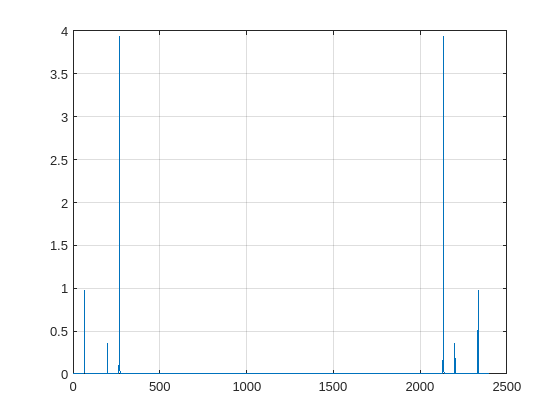

plot(f, p)
grid on

## Task 5

This signal has three dominant frequencies, and there are six peaks in the plot. `fft` returns the two-sided spectrum, which you'll learn more later in the lesson.

To plot the spectrum in decibels (dB), you can use 10log10(*p*), where *p* is the power spectrum.

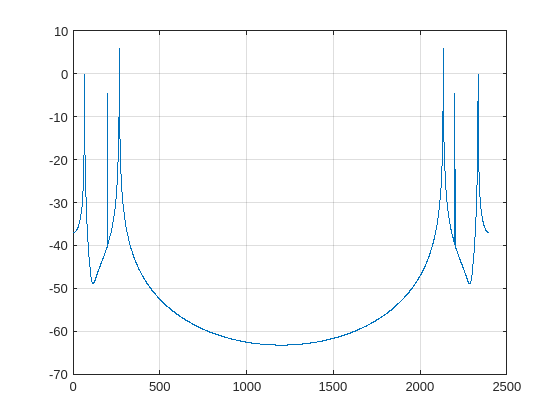

plot(f, 10*log10(p))
grid on